# Control PID para sistemas de 2 Orden

## Ecuación de retroalimentación

Partimos de un sistema con retrolimentación

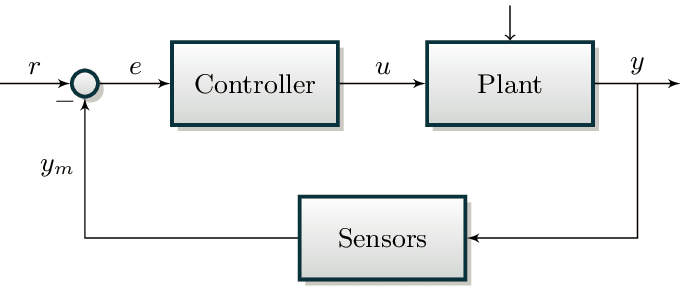

Con las ecuaciones de Laplace para $r,y,u,y_{m\;}$


$$\begin{array}{l}
E\left(s\right)=R\left(s\right)-Y_{m\;} \left(s\right)\\
U\left(s\right)=C\left(s\right)\;E\left(s\right)\\
Y\left(s\right)=P\left(s\right)\;U\left(s\right)\\
Y_{m\;} \left(s\right)=H\left(s\right)Y\left(s\right)
\end{array}$$


Generalmente $G\left(s\right)=C\left(s\right)P\left(s\right)$. La idea es relacionar $r$ con $y$


$$\begin{array}{l}
Y\left(s\right)=P\left(s\right)\;U\left(s\right)=P\left(s\right)C\left(s\right)\;E\left(s\right)=P\left(s\right)C\left(s\right)\left(R\left(s\right)-Y_{m\;} \left(s\right)\right)=P\left(s\right)C\left(s\right)\left(R\left(s\right)-H\left(s\right)Y\left(s\right)\right)\\
Y\left(s\right)=P\left(s\right)C\left(s\right)R\left(s\right)-P\left(s\right)C\left(s\right)H\left(s\right)Y\left(s\right)\\
Y\left(s\right)\left(1+P\left(s\right)C\left(s\right)H\left(s\right)\right)=P\left(s\right)C\left(s\right)R\left(s\right)\\
Y\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)H\left(s\right)}R\left(s\right)
\end{array}$$


Para simplificar un poco las cosas $H\left(s\right)=1$


$$Y\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}R\left(s\right)=F\left(s\right)R\left(s\right)\approx R\left(s\right);\;$$
      
$$F\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}\approx 1$$


Ahora descomponemos $P\left(s\right)=\frac{P_{N\;} }{P_{D\;} }$ y $C\left(s\right)=\frac{C_{N\;} }{C_{D\;} }$


$$F\left(s\right)=$$

$$\frac{\frac{P_{N\;} }{P_{D\;} }\frac{C_{N\;} }{C_{D\;} }}{1+\frac{P_{N\;} }{P_{D\;} }\frac{C_{N\;} }{C_{D\;} }}=$$

$$\frac{P_{N\;} C_{N\;} }{P_{D\;} C_{D\;} +P_{N\;} C_{N\;} }$$


## Sistema de segundo orden

Recordando una planta cuya dínamica se puede respresentar por un sistema de segundo orden.


$$P\left(s\right)=\frac{P_{N\;} }{P_{D\;} }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 }{s^{2\;} +2\zeta \omega {\;}_n \;s+\omega_{n\;}^2 }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 }{s^{2\;} +2\zeta \omega {\;}_n \;s\;+\zeta {\;}^2 \omega {\;}^{2\;} +\omega_{n\;}^2 -\zeta {\;}^2 \omega {\;}^{2\;} }=k_{\textrm{dc}\;} \frac{\omega {\;}_n^2 }{{\left(s^{\;} +\zeta \omega {\;}_n \right)}^2 +\omega_{n\;}^2 \left(1-\zeta {\;}^{2\;} \right)}$$


clc;
clear all;
close all;
s = tf('s');
P = 1/(s^2 + 10*s + 20)

P =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



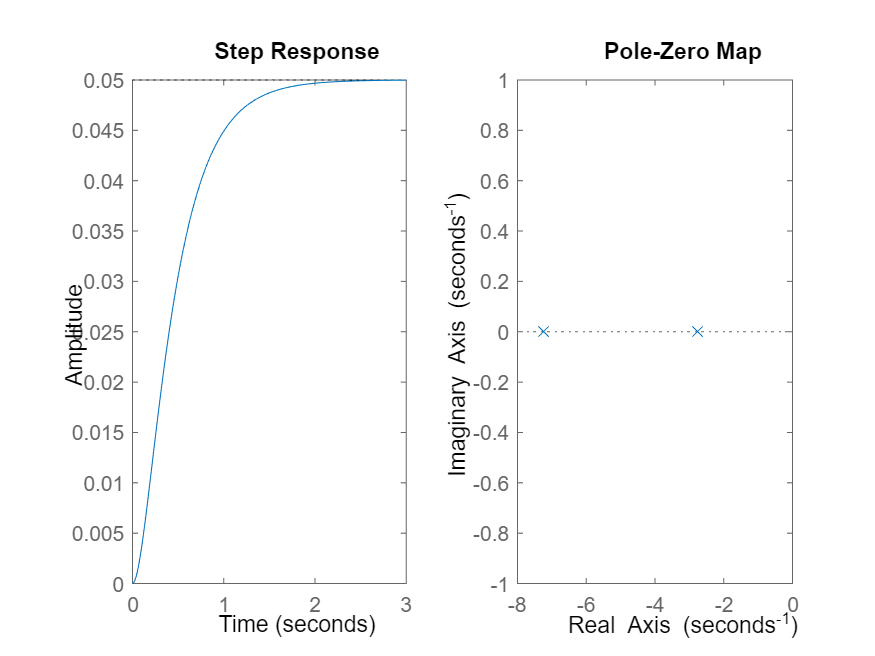

figure('Name','Sistema segundo orden');
subplot(1,2,1);
step(P);
subplot(1,2,2);
pzmap(P);

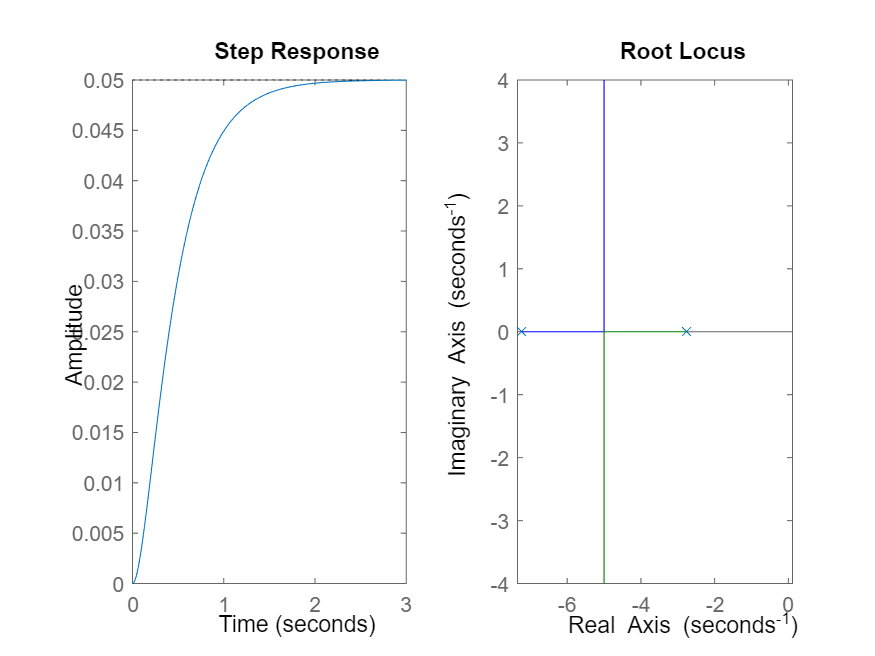

rlocus(P)

% axis([-8 1 -15 15]);

subplot(1,2,1)
step(P)

% axis([0 2 0 0.1]);

## Control PID

Se representa por un control proporcional, integral y derivativo al error


$$C\left(s\right)=\frac{C_{N\;} }{C_{D\;} }=K_{p\;} +\frac{K_{I\;} }{s}+K_{D\;} s=\frac{K_D s^2 +K_P s+K_I }{s}$$


Combinando con la ecuación de sistemas de segundo orden


$$P\left(s\right)=\frac{P_{N\;} }{P_{D\;} }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 }{s^{2\;} +2\zeta \omega {\;}_n \;s+\omega_{n\;}^2 }$$



$$F\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}=$$

$$\frac{P_{N\;} C_{N\;} }{P_{D\;} C_{D\;} +P_{N\;} C_{N\;} }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}$$


## Control P

Veamos los efectos por separado de cada controlador, $K_D =0,{\;K}_I =0,K_P >0$ 


$$F\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}=$$

$$\frac{P_{N\;} C_{N\;} }{P_{D\;} C_{D\;} +P_{N\;} C_{N\;} }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}$$



$$F\left(s\right)=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_P s\right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_P s\right)\;}=$$

$$\frac{\left(s+0\right)\left(k_{\textrm{dc}\;} \omega {\;}_n^2 K_P \right)\;}{\left(s+0\right)\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 +\left(k_{\textrm{dc}\;} \omega {\;}_n^2 K_P \right)\right)\;};$$

$$F\left(s\right)=\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 K_P \right)\;}{\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)\right)\;}$$


Comparando con el sistema de segundo orden


$$P\left(s\right)=\frac{P_{N\;} }{P_{D\;} }=\frac{{k_{\textrm{dc}\;} }^{\prime } \omega {\;}_n^2 }{s^{2\;} +2\zeta^{\prime } \omega {\;}_n \;s+{\prime \omega }_{n\;}^2 }$$


$\prime \zeta \prime \omega {\;}_n \;$=constante


$${\prime \omega \;}_{n\;}^2 =$$

$$\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)\;\;\;\;\;\;\;\;\to \;\;\;\;\;{\omega^{\prime } }_n \;\;\alpha \;K_P$$
  

$K_P$ promueve que la frecuencia natural incremente, por tanto, el sistema se convierte en subamortiguado, es decir, los polos se elejan del eje real.

Se obtiene mas energía $\lim_{s\to 0} \;F\left(s\right)=$$\lim_{s\to 0,\;t\to \infty } \;\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 K_P \right)\;}{\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)\right)\;}=\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 K_P \right)\;}{\left(\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)\right)\;}=\frac{k_{\textrm{dc}\;} K_P }{\left(1+k_{\textrm{dc}\;} K_P \right)}\approx 1$

clc;
% close all;
Kp = 20;

for i = 1:3
    C(:,:,i) = pid(Kp);
    Kp = Kp*2;
end

T = feedback(C*P,1)

T(:,:,1,1) =
 
        20
  ---------------
  s^2 + 10 s + 40
 

T(:,:,2,1) =
 
        40
  ---------------
  s^2 + 10 s + 60
 

T(:,:,3,1) =
 
         80
  ----------------
  s^2 + 10 s + 100
 
3x1 array of continuous-time transfer functions.



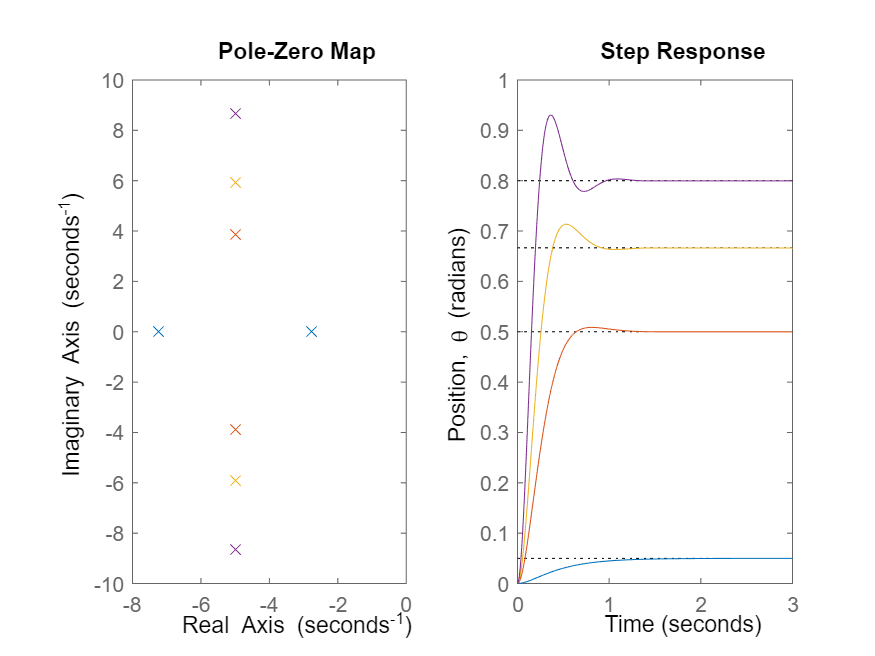


figure('Name','Control P');
subplot(1,2,1);
pzmap(P, T(:,:,1), T(:,:,2), T(:,:,3));   


subplot(1,2,2);
step(P, T(:,:,1), T(:,:,2), T(:,:,3));
ylabel('Position, \theta (radians)');

% legend('Natural, Kp = 10', 'Kp = 20', 'Kp = 30');

## Control PI

Veamos los efectos en conjunto con el controlador propocional e integral, $K_D =0,{\;K}_I >0,K_P >0$ 


$$F\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}=$$

$$\frac{P_{N\;} C_{N\;} }{P_{D\;} C_{D\;} +P_{N\;} C_{N\;} }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}$$



$$F\left(s\right)=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_P s+K_I \right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_P s+K_I \right)\;}=$$

$$\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)\left(K_P s+K_I \right)\;}{\left(s^{3\;} +2\zeta \;\omega {\;}_n \;s^2 +\omega_{n\;}^2 s+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_P s+K_I \right)\right)}$$



$$F\left(s\right)=\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)\left(K_P s+K_I \right)\;}{\left(s^{3\;} +2\zeta \;\omega {\;}_n \;s^2 +\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)s+k_{\textrm{dc}\;} \omega {\;}_n^2 K_I \right)\;}$$


Raices reales y reales conjugadas


$$\left(s+\beta_{i\;} \right)\left(s{+\beta }_{i+1} \right)\left(s+\gamma_j +i\delta_{j\;} \right)\left(s+\gamma {\;}_j -i\delta_{j\;} \right)=\left(s+\beta_{i\;} \right)\left(s{+\beta }_{i+1} \right)\left(s^2 +2\gamma_{j\;} s+\left(\gamma_{j\;}^2 +\delta_{j\;}^{2\;} \right)\;\right)$$


Como se ve en el modelo anterior es un sistema de 3er orden, lo cual complica el análisis. Sin embargo, en general la parte integral se agrega para que el sistema llegue a la referencia marcada, en este caso un escalon unitario. Para ello se obtiene el limite cuando `s=0`


$$\lim_{t\to \infty \;} \;F\left(s\right)=$$

$$\lim_{s\to 0} \;\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)\left(K_P s+K_I \right)\;}{\left(s^{3\;} +2\zeta \;\omega {\;}_n \;s^2 +\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)s+k_{\textrm{dc}\;} \omega {\;}_n^2 K_I \right)\;}=\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)\left(K_P \left(0\right)+K_I \right)\;}{\left({\left(0\right)}^{3\;} +2\zeta \;\omega {\;}_n \;{\left(0\right)}^2 +\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)\left(0\right)+k_{\textrm{dc}\;} \omega {\;}_n^2 K_I \right)\;}=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 K_I }{k_{\textrm{dc}\;} \omega {\;}_n^2 K_I }=1$$


Por tanto, el control proporcional e integral (PI), ayuda a que el sistema obtenga toda la energía.

También se puede observar que el sistema tiene a oscilar debido al último termino $k_{\textrm{dc}\;} \omega {\;}_n^2 K_I$, cuando aumenta, tiene a formar polos separados del eje real.

clc;
close all;

Kp = 300; Ki = 70;
% Kp = 300; Ki = 140;
% Kp = 150; Ki = 70;
% Kp = 35; Ki = 70;
for i = 1:2
    C(:,:,i) = pid(Kp,Ki,0);
    Ki = Ki*2;
end

Ki = 70;

for i = 3:4
    Kp = Kp/2;
    C(:,:,i) = pid(Kp,Ki,0);
end

T = feedback(C*P,1)

T(:,:,1,1) =
 
         300 s + 70
  -------------------------
  s^3 + 10 s^2 + 320 s + 70
 

T(:,:,2,1) =
 
         300 s + 140
  --------------------------
  s^3 + 10 s^2 + 320 s + 140
 

T(:,:,3,1) =
 
         150 s + 70
  -------------------------
  s^3 + 10 s^2 + 170 s + 70
 

T(:,:,4,1) =
 
         75 s + 70
  ------------------------
  s^3 + 10 s^2 + 95 s + 70
 
4x1 array of continuous-time transfer functions.



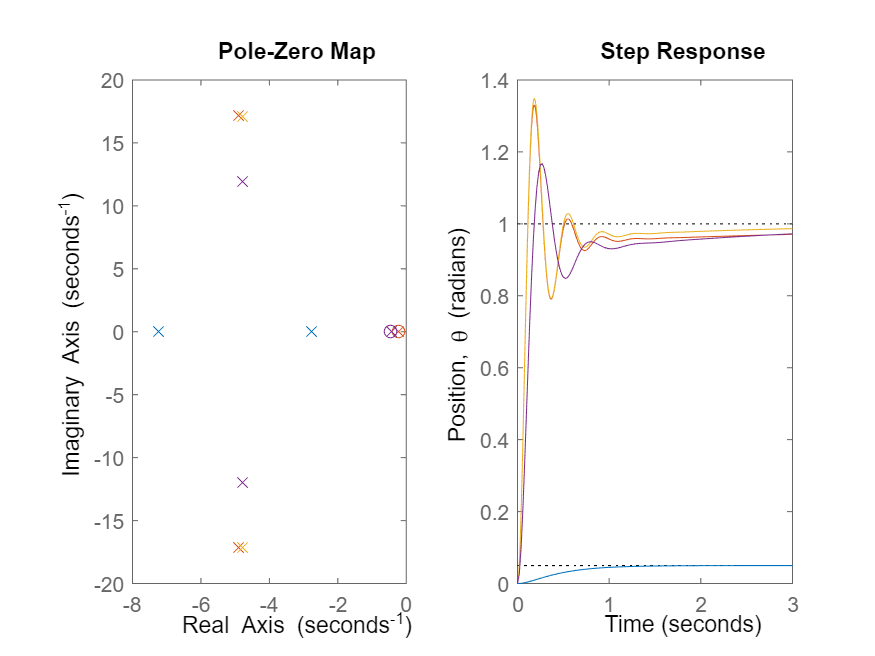


figure('Name','Control PI');
subplot(1,2,1);
pzmap(P, T(:,:,1), T(:,:,2), T(:,:,3));%, T(:,:,4));

subplot(1,2,2)
step(P, T(:,:,1), T(:,:,2), T(:,:,3));%, T(:,:,4));
axis([0 3 0 1.4])
ylabel('Position, \theta (radians)');

% legend('Natural',' Kp = 300; Ki = 70', 'Kp = 300; Ki = 140', 'Kp = 150; Ki = 70', 'Kp = 75; Ki = 70');

## Control PD

Veamos los efectos en conjunto con el controlador propocional e integral, $K_D >0,{\;K}_I =0,K_P >0$ 


$$F\left(s\right)=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}=$$

$$\frac{P_{N\;} C_{N\;} }{P_{D\;} C_{D\;} +P_{N\;} C_{N\;} }=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s+K_I \right)\;}$$



$$F\left(s\right)=\frac{k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s\right)\;}{s\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 \right)+k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s^2 +K_P s\right)\;}=$$

$$\frac{\left(s+0\right)\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)\left(K_D s+K_P \right)\;}{\left(s+0\right)\left(s^{2\;} +2\zeta \;\omega {\;}_n \;s+\omega_{n\;}^2 +k_{\textrm{dc}\;} \omega {\;}_n^2 \left(K_D s+K_P \right)\right)\;}$$



$$F\left(s\right)=\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)\left(K_D s+K_P \right)\;}{\left(s^{2\;} +\left(2\zeta \;\omega {\;}_n +k_{\textrm{dc}\;} \omega {\;}_n^2 K_D \right)\;s+\omega_{n\;}^2 \left(1+K_{p\;} \right)\right)\;}=$$

$$\frac{\left(k_{\textrm{dc}\;} \omega {\;}_n^2 \right)K_D \left(s+\frac{K_P }{K_D }\right)\;}{\left(s^{2\;} +\left(2\zeta \;\omega {\;}_n +k_{\textrm{dc}\;} \omega {\;}_n^2 K_D \right)\;s+\omega_{n\;}^2 \left(1+{k_{\textrm{dc}\;} K}_{p\;} \right)\right)\;}$$


El modelo anterior es un sistema de segundo orden con un polo $s=-\frac{K_P }{K_D }$, podemos comparar los zeros con un sistema de segundo orden, similar a lo que se realizó con el contor P.

${2\prime \zeta }^{\prime } \omega {\;}_n \;$=$2\zeta \;\omega {\;}_n +k_{\textrm{dc}\;} \omega {\;}_n^2 K_D \;\;\;\;\to \;\;\;\;\;\prime \zeta \;\;\alpha \;\;\;\;K_D \;\;$


$${\prime \omega }_{n\;}^2 =$$

$$\omega_{n\;}^2 \left(1+k_{\textrm{dc}\;} K_P \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to \;\;\;\;\;\prime \omega_{n\;} \;\;\alpha \;\;\;\;K_p \;\;$$


Se puede observar que $K_D$ promueve que el factor de amortiguamiento incremente, por tanto, el sistema se convierte en sobreamortiguado, es decir, los polos se acercan al eje real.

Mientras que $K_P$ promueve que la frecuencia natural incremente, por tanto, el sistema se convierte en subamortiguado, es decir, los polos se elejan del eje real.


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\cos \left(\omega \;t\right)=\omega \;\textrm{sen}\left(\omega \;t\right)\to \frac{s}{s^2 +\omega^2 }\\
\frac{s}{\left(s^2 +\omega^2 \right)\left(s+\alpha \right)}\to \omega \;e^{-\alpha t} \textrm{sen}\left(\omega \;t\right)
\end{array}$$


clc;
close all;

Kp = 300; Kd = 10;
% Kp = 1; Kd = 1e2;

for i = 1:3
    C(:,:,i) = pid(Kp,0,Kd);
    Kd = Kd*2;
end

% C = pid(Kp,0,Kd);
T = feedback(C*P,1)

T(:,:,1,1) =
 
     10 s + 300
  ----------------
  s^2 + 20 s + 320
 

T(:,:,2,1) =
 
     20 s + 300
  ----------------
  s^2 + 30 s + 320
 

T(:,:,3,1) =
 
     40 s + 300
  ----------------
  s^2 + 50 s + 320
 

T(:,:,4,1) =
 
         75 s + 70
  ------------------------
  s^3 + 10 s^2 + 95 s + 70
 
4x1 array of continuous-time transfer functions.



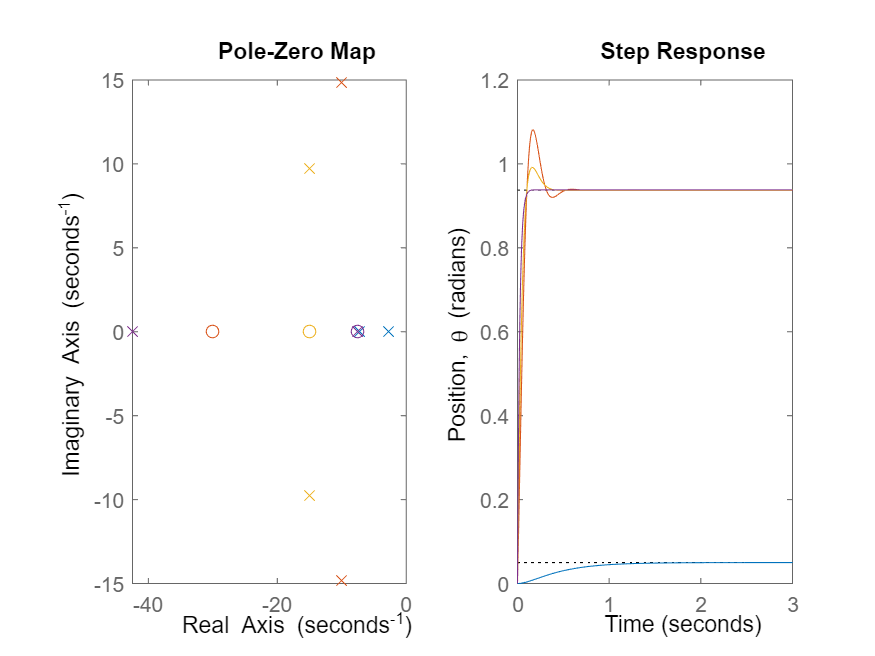


figure('Name','Control PD');
subplot(1,2,1);
pzmap(P, T(:,:,1), T(:,:,2), T(:,:,3));   
% rlocus(P, T(:,:,2))

subplot(1,2,2)
step(P, T(:,:,1), T(:,:,2), T(:,:,3));
ylabel('Position, \theta (radians)');

% legend('Natural',' Kp = 300; Kd = 10', 'Kp = 300; Kd = 20', 'Kp = 300; Kd = 10');

## PID

clc;
close all;



Kp = 150; Ki = 40; Kd = 10;
% Kp = 300; Ki = 70; Kd = 20;
% Kp = 300; Ki = 140; Kd = 40;

C = pid(Kp,Ki,Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 150, Ki = 40, Kd = 10
 
Continuous-time PID controller in parallel form.



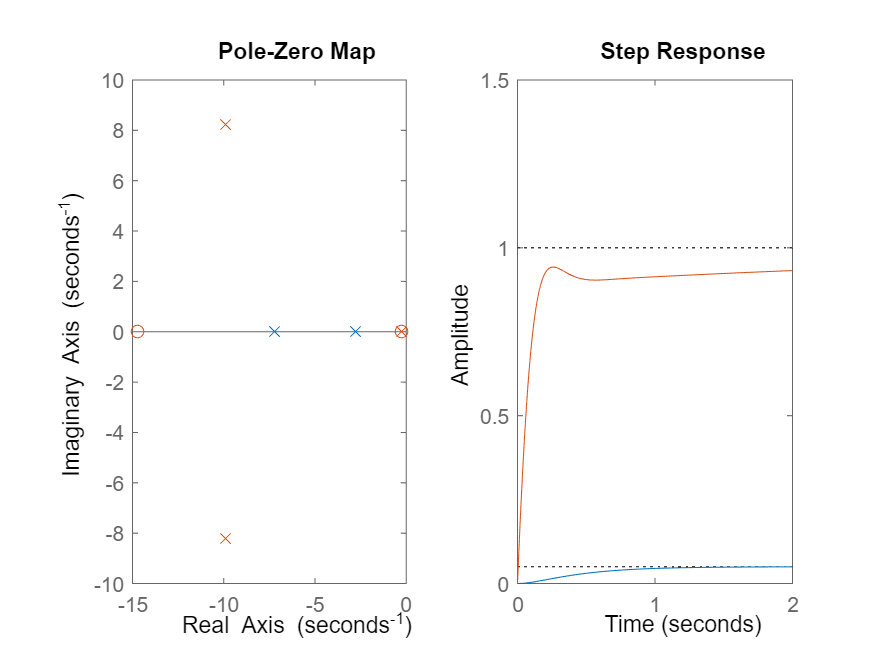

T = feedback(C*P,1);

figure(5)
subplot(1,2,1);
pzmap(P,T);
% axis([-30 1 -20 20]);

subplot(1,2,2)
step(P,T)
axis([0 2 0 1.5]);

## PID automatic tuning

pidTuner(P,C)